%% AMSC 420 Group Homework 2
% Group: Robert "Eddie" Bull, Alexander Klein
clearvars
h = 0.01;
C_s = [0 1; 1 1];


## SIR Model


% Establish important params first
format shortG
T_max = 120;

[Y, V, t_0, N, Om] = setup("project5_data.xlsx");

% First, let's gather all we need from the 120 models.
[J_1s, J_2s, J_infs, I_t, Y_t, rhos, gammas] = get_variables(Y, V, Om, C_s, 7, T_max, t_0, N);

% Setting initial conditions for Euler's
initials = [N, I_t(1), 0];

% After the loop, we have all that we need to start getting data.
% So now let's find the minimum value and index of the J values.
% Returns two row vectors denoting the minimum values and indices of J_p
[val_1, ind_1] = min(J_1s);
[val_2, ind_2] = min(J_2s);
[val_inf, ind_inf] = min(J_infs);

% Now we have all the data we need for T_max = 120

[pred_1, pred_2, pred_inf, rs_pred, gs_pred] =...
    third_prediction_SIR(Y, V, Om, C_s, 7, t_0, N);


disp("The optimal J-values for p = 1 are: [" + join(string(val_1), ', ') + "]")

The optimal J-values for p = 1 are: [4661.258759, 132302.2069]


The optimal values for p = 1 and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.39 0.546]
rho, gamma = [0.13708, 0.0013891]
The predicted t for when I < 5 is = 56


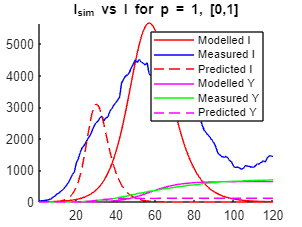

The optimal values for p = 1 and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.38 0.513]
rho, gamma = [0.13708, 0.0013891]
The predicted t for when I < 5 is = 61


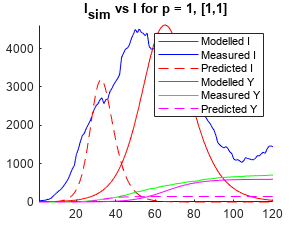

plot_graph(Om(ind_1, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_1, 1, C_s,...
    rs_pred, gs_pred, Om(pred_1, :))


disp("The optimal J-values for p = 2 are: [" + join(string(val_2), ', ') + "]")

The optimal J-values for p = 2 are: [281747.3846615, 187335583.3361]


The optimal values for p = 2 and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.4 0.56]
rho, gamma = [0.14199, 0.0013557]
The predicted t for when I < 5 is = 58


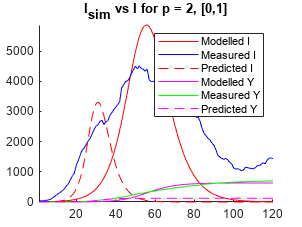

The optimal values for p = 2 and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.4 0.54]
rho, gamma = [0.14199, 0.0013557]
The predicted t for when I < 5 is = 63


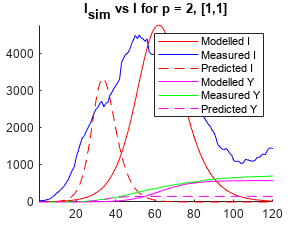

plot_graph(Om(ind_2, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_2, 2, C_s,...
    rs_pred, gs_pred, Om(pred_2, :))


disp("The optimal J-values for p = inf are: [" + join(string(val_inf), ', ') + "]")

The optimal J-values for p = inf are: [83.202944, 2187.2201]


The optimal values for p = inf and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.37 0.5365]
rho, gamma = [0.13055, 0.0012436]
The prediction did not find a t such that I(t) < 5!


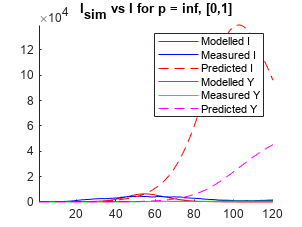

The optimal values for p = inf and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.4 0.56]
rho, gamma = [0.13055, 0.0012436]
The predicted t for when I < 5 is = 64


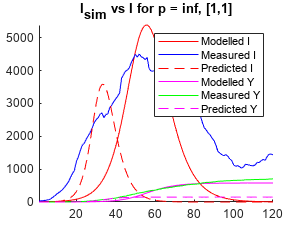

plot_graph(Om(ind_inf, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_inf, 3, C_s,...
    rs_pred, gs_pred, Om(pred_inf, :))

## SIR Validation

disp("Begin Validation testing")

Begin Validation testing


disp("")
% Here, we'll use the validation set (project5_validation) instead of the
% normal dataset we've used previously.
T_max = 120;

[Y, V, t_0, N, Om] = setup("project5_validation.xlsx");

[J_1s, J_2s, J_infs, I_t, Y_t, rhos, gammas] = get_variables(Y, V, Om, C_s, 7, T_max, t_0, N);

[val_1, ind_1] = min(J_1s);
[val_2, ind_2] = min(J_2s);
[val_inf, ind_inf] = min(J_infs);

% Setting initial conditions for Euler's
initials = [N, I_t(1), 0];

[pred_1, pred_2, pred_inf, rs_pred, gs_pred] =...
    third_prediction_SIR(Y, V, Om, C_s, 7, t_0, N);

% Now we have all the data we need for T_max = 120

disp("The optimal J-values for p = 1 are: [" + join(string(val_1), ", ") + "]")

The optimal J-values for p = 1 are: [3006.96939, 72293.9147]


The optimal values for p = 1 and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.39 0.5265]
rho, gamma = [0.10429, 0.0015905]
The prediction did not find a t such that I(t) < 5!


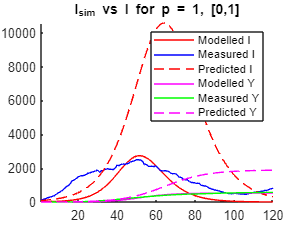

The optimal values for p = 1 and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.4 0.52]
rho, gamma = [0.10429, 0.0015905]
The prediction did not find a t such that I(t) < 5!


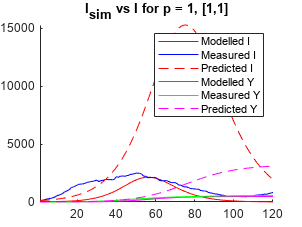

plot_graph(Om(ind_1, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_1, 1, C_s,...
    rs_pred, gs_pred, Om(pred_1, :))


disp("The optimal J-values for p = 2 are: [" + join(string(val_2), ", ") + "]")

The optimal J-values for p = 2 are: [107823.590878, 56034861.6084]


The optimal values for p = 2 and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.4 0.54]
rho, gamma = [0.11591, 0.001574]
The prediction did not find a t such that I(t) < 5!


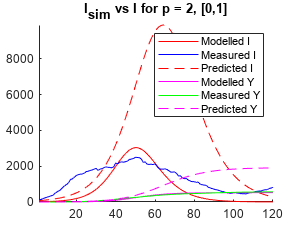

The optimal values for p = 2 and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.39 0.5265]
rho, gamma = [0.11591, 0.001574]
The prediction did not find a t such that I(t) < 5!


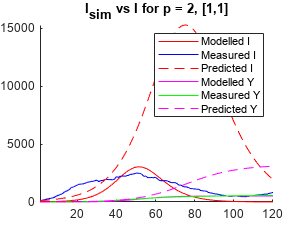

plot_graph(Om(ind_2, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_2, 2, C_s,...
    rs_pred, gs_pred, Om(pred_2, :))


disp("The optimal J-values for p = inf are: [" + join(string(val_inf), ", ") + "]")

The optimal J-values for p = inf are: [50.036355, 1301.3144]


The optimal values for p = inf and [c_I, c_Y] = [0, 1] are:
alpha, beta = [0.37 0.518]
rho, gamma = [0.11506, 0.001435]
The prediction did not find a t such that I(t) < 5!


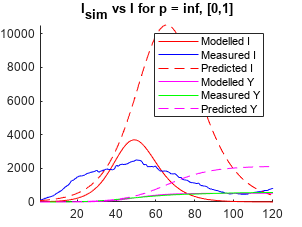

The optimal values for p = inf and [c_I, c_Y] = [1, 1] are:
alpha, beta = [0.4 0.56]
rho, gamma = [0.11506, 0.001435]
The prediction did not find a t such that I(t) < 5!


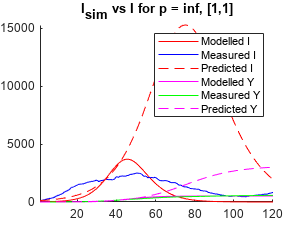

plot_graph(Om(ind_inf, :), initials, T_max, h, N, I_t, Y_t, rhos, gammas, ind_inf, 3, C_s,...
    rs_pred, gs_pred, Om(pred_inf, :))

Here are the functions we ended up using for the SIR model.

function optimals = optimize_hat_vals(observed, simulated, T_max)
options = optimoptions('linprog','Display','none');
% Row vector of optimized values given observed and simulated arrays
optimals = zeros(1, 3);
r_k = zeros(T_max,1);
f_k = zeros(T_max,1);
for k = 1:(T_max)
    r_k(k) = observed(k)/simulated(k);
    % Don't consider values of r that aren't in [0,1]
    if r_k(k) >= 0 && r_k(k) <= 1
        f_k(k,1) = sum(abs(transpose(observed(1,1:T_max)) - r_k(k)*simulated(1:T_max)));
    else
        f_k(k,1) = inf;
    end
end
[~,index] = min(f_k);
optimals(1) = r_k(index);

% Trying closed form solution with I_t and I_sim
optimals(2) = min(sum(observed(1:T_max)'.*simulated(1:T_max))./sum(simulated(1:T_max).^2), 1);

% And then the linear program with I_t. This doesn't seem to work.
A = [-1 * ones(2*(T_max), 1), zeros(2*(T_max), 1)];
b = zeros(2*(T_max), 1);
f = [1;0];
for j = 1:(size(A, 1))
    A(j,2) = (-1)^mod(j,2)...
        *simulated(ceil(j/2));
    b(j,1) = (-1)^mod(j,2)*observed(ceil(j/2));
end
x = linprog(f,A,b, [], [], [0; 0], [inf; 1], options);
optimals(3) = x(2);

end

% This is the euler function we'll use for the different alphas and betas
% Should take inits as S I R and functions as S I R
function results = euler_SIR(alpha, beta, inits, T_max, step, N)
% Initialize diffeqs to pretty up code
dS = @(a, b, S, I) -1 * b * S * (I/N);
dI = @(a, b, S, I) b * S * (I/N) - a * I;
dR = @(a, b, S, I) a * I;

% S_sim, I_sim, R_sim
results = zeros([T_max/step, 3]);
results(1, :) = inits;
index = 1;


for t=step:step:T_max-1
    index = index + 1;
    % Assign to a temporary variable for easy reading...
    S = results(index - 1, 1);
    I = results(index - 1, 2);
    R = results(index - 1, 3);

    % Calculate using the defined function above, and store to array
    results(index, 1) = S + step * dS(alpha, beta, S, I);
    results(index, 2) = I + step * dI(alpha, beta, S, I);
    results(index, 3) = R + step * dR(alpha, beta, S, I);
end

results = downsample(results, 1/step);
end

% I use this function as a holder for drawing graphs relating to predicted
% versus measured values.
function plot_graph(Omega_set, initials, T_max, h, N, I, Y, rhos, gammas, indices, p, C_s, ...
    rs_pred, gs_pred, Omega_pred)
p_vals = ["1", "2", "inf"];
p_val = p_vals(p);

for i=(1:size(Omega_set, 1))

    euler_res = euler_SIR(Omega_set(i, 1), Omega_set(i, 2), initials, T_max, h, N);
    euler_pred = euler_SIR(Omega_pred(i, 1), Omega_pred(i, 2), initials, T_max, h, N);
    rho_pred = rs_pred(i, p);
    gamma_pred = gs_pred(i, p);
    rho = rhos(indices(1), p);
    gamma = gammas(indices(1), p);
    disp('The optimal values for p = ' + p_val + " and [c_I, c_Y] = [" + join(string(C_s(i, :)), ', ') + "] are:")
    disp('alpha, beta = [' + join(string(Omega_set(i, :))) + "]")
    disp('rho, gamma = [' + string(rho) + ", " + string(gamma) + "]")

    [mindex, ~] = find(rho_pred * euler_pred(10:T_max, 2) < 5);
    if ~isempty(mindex)
        disp('The predicted t for when I < 5 is = ' + string(mindex(1)))
    else
        disp('The prediction did not find a t such that I(t) < 5!')
    end


    figure
    hold on

    plot(rho * euler_res(:, 2), 'r-')
    plot(I(:), 'b-')
    plot(rho_pred * euler_pred(:, 2), 'r--')

    plot(gamma * euler_res(:, 3), 'm-')
    plot(Y, 'g-')
    plot(gamma_pred * euler_pred(:, 3), 'm--')

    axis tight

    hold off
    title("I_{sim} vs I for p = " + p_val + ", " + "[" + join(string(C_s(i, :)), ",") + "]")
    legend('Modelled I', 'Measured I', 'Predicted I', 'Modelled Y', 'Measured Y', 'Predicted Y')
end
end

% This function is the start of me implementing both the validation set and
% the 1/3 prediction.
function [J_1s, J_2s, J_infs, I_t, Y_t, rhos, gammas] = get_variables(Y, V, Om, C_s, Tau_0, T_max, t_0, N)
h = 0.01;

% Setting infections and deaths
Y_t = Y(t_0:(T_max + t_0 - 1));

% Setting infection rates
I_t = V((t_0:(T_max + t_0 - 1)) + Tau_0) - V((t_0:(T_max + t_0 - 1)) - Tau_0);

% Make lists for the J values so we can get the minimum when it's important
J_1s = zeros([size(Om, 1), size(C_s, 1)]);
J_2s = zeros([size(Om, 1), size(C_s, 1)]);
J_infs = zeros([size(Om, 1), size(C_s, 1)]);

% Initialize gamma and rho vectors
gammas = zeros(size(Om,1),3);
rhos = zeros(size(Om,1),3);

% Setting initial conditions for Euler's
initials = [N, I_t(1), 0];

for i=1:size(Om, 1)
    % syms f(gamma)
    % First, get the results for the simulation.
    set = Om(i, :);
    r = euler_SIR(set(1), set(2), initials, 120, h, N);

    % Then, for each pair, we calculate rho and gamma for each p value and
    % in the same loop, we calculate three J values for each p value

    % We'll do gamma first
    gammas(i, :) = optimize_hat_vals(Y_t, r(1:T_max, 3), T_max);

    % Now we'll optimize rho
    rhos(i, :) = optimize_hat_vals(I_t, r(1:T_max, 2), T_max);

    % Precalculating the rho and gamma summations for later
    rho_sum = [sum(abs(I_t' - rhos(i, 1) .* r(1:T_max, 2))),...
        sum((I_t' - rhos(i, 2) .* r(1:T_max, 2)).^2), ...
        max(abs(I_t' - rhos(i, 3) .* r(1:T_max, 2)))];

    gamma_sum = [sum(abs(Y_t' - gammas(i, 1) * r(1:T_max, 3))), ...
        sum((Y_t' - gammas(i, 2) .* r(1:T_max, 3)).^2), ...
        max(abs(Y_t' - gammas(i, 3) * r(1:T_max, 3)))];

    % Then we calculate the two different cI and cY
    % Cool method that lets us redefine C_s with no consequence!
    % Multiplies rho and gamma sums by the cI and cY values defined
    % above in C_s and turns it into a row vector.
    J_1 = sum(C_s .* [rho_sum(1), gamma_sum(1)], 2)';
    J_2 = sum(C_s .* [rho_sum(2), gamma_sum(2)], 2)';
    J_inf = sum(C_s .* [rho_sum(3), gamma_sum(3)], 2)';

    J_1s(i, :) = J_1;
    J_2s(i, :) = J_2;
    J_infs(i, :) = J_inf;
end
end

% Replacing the entire first section of code, I use this one to establish
% basic variables for the proceeding questions.
function [Y, V, t_0, N, Om] = setup(filename)

T = readtable(filename);

N = table2array(T(2, 12));
Y = table2array(T(3, 13:1103));
V = table2array(T(2, 13:1103));

[~, index] = find(V > 5);
t_0 = index(1);


% Establishing Omega
R_0 = 0.8:0.05:2.2;
alpha = 0.05:0.01:0.4;
s_R = size(R_0, 2);
s_a = size(alpha, 2);

offset = 0;
% Actually creating Omega
Om = zeros([s_a * s_R, 2]);
for i = 1:s_a
    for j = 1:s_R
        Om(i + (offset * (s_R - 1)) + j - 1, 1) = alpha(i);
        Om(i + (offset * (s_R - 1)) + j - 1, 2) = alpha(i) * R_0(j);
    end
    offset = offset + 1;
end

end

% The crux of the second part of question 1, this function will involve
% plotting the predicted curve using a third of the data, and revealing
% a predicted t such that I_sim(t) < 5
function [ind_1_pred, ind_2_pred, ind_inf_pred, rhos_pred, gammas_pred] = ...
    third_prediction_SIR(Y, V, Om, C_s, Tau_0, t_0, N)
% First, call EulerSIR to find predicted values for T_max = 120
% Then, we optimize the J values based on the first third or T = 40
% Finally, we use those optimized parameters to check our prediction
[J_1s, J_2s, J_infs, ~, ~, rhos, gammas] = ...
    get_variables(Y, V, Om, C_s, Tau_0, 40, t_0, N);

[~, ind_1_pred] = min(J_1s);
[~, ind_2_pred] = min(J_2s);
[~, ind_inf_pred] = min(J_infs);

rhos_pred = [rhos(ind_1_pred, 1) rhos(ind_2_pred, 2) rhos(ind_inf_pred, 3)];
gammas_pred = [gammas(ind_1_pred, 1) gammas(ind_2_pred, 2) gammas(ind_inf_pred, 3)];

end
